Calculates the normalized active force in muscle fibers with respect to the active force-length relationship (applies to all muscles in OpenSim musckuloskeletal model)

${\overset{~}{l} }^M$ is the normalized muscle fiber length

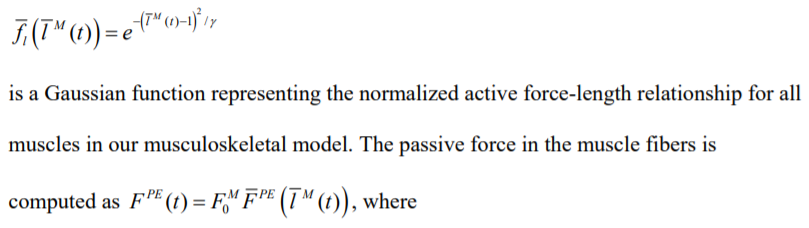

function F_L = Thelen2003_Active_Force_Length(fib_len_norm)
    % KshapeActive is given as 0.45 in GitHub documentation
    KshapeActive = 0.45;% a shape factor for the Gaussian active force-length relationship
    F_L = zeros(size(fib_len_norm));
    for i = 1:length(fib_len_norm)
        lM_norm = fib_len_norm(i);
%         F_L(i) = exp(-(lM_norm - 1).^2)/KshapeActive;
        x = (lM_norm -1)^2;
        F_L(i) = exp(-x / KshapeActive);
    end
end